cd FlashVsNoFlash/Dataset

% Read sensor images

ambient = imread('Illumination/Objects_008_ambient.png');
flash = imread('Illumination/Objects_008_flash.png');

ambient = double(ambient);
flash = double(flash);

% Read color matrices and calibration illuminants
ambient_exif = load('EXIF/Objects_008_ambient.mat');
flash_exif = load('EXIF/Objects_008_flash.mat');

ambient_color_matrix = ambient_exif.metadata.ColorMatrix1;
ambient_calibration_illuminant = ambient_exif.metadata.CalibrationIlluminant1;

flash_color_matrix = flash_exif.metadata.ColorMatrix1;
flash_calibration_illuminant = flash_exif.metadata.CalibrationIlluminant1;

% Convert to RGB color space and normalize between 0 and 1
A_lin = cameraToXYZtoSRGB(ambient,ambient_color_matrix,ambient_calibration_illuminant);
F_lin = cameraToXYZtoSRGB(flash,flash_color_matrix,flash_calibration_illuminant);
A_lin = A_lin/255;
F_lin = F_lin/255;


% Reading non-linear images
A = imread('Photo/Objects_008_ambient.png');
F = imread('Photo/Objects_008_flash.png');
A = double(A);
F = double(F);
A = A/255;
F = F/255;

% Denoising
A_Base = bilateralFilter(A,8,3);
A_NR = jointBilateralFilter(A,F,3,8);

% Detail transfer
epsilon = 0.02;
F_Base = bilateralFilter(F,8,3);
F_Detail = (F + epsilon) ./ (F_Base + epsilon);

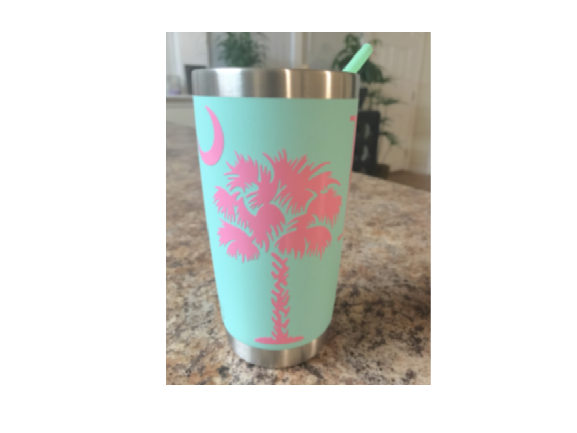

% Plotting figures
figure();imshow(A_NR);

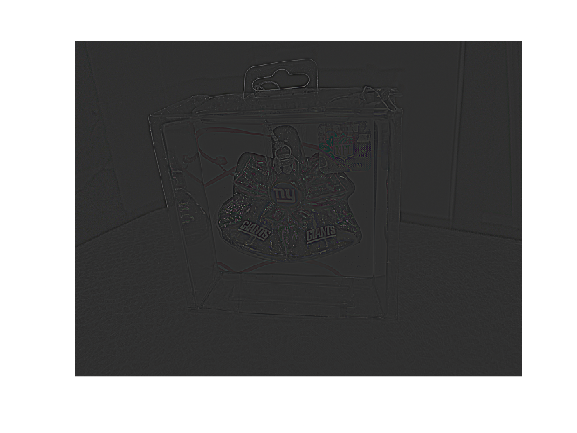

figure();imshow(F_Detail/max(F_Detail,[],"all"));

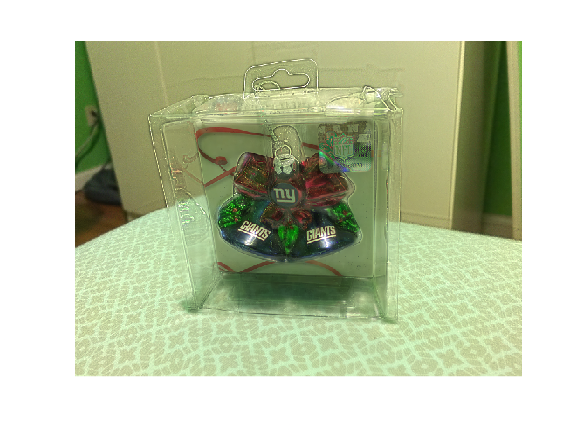

figure(); imshow(A_NR .* F_Detail);

% Mask business
% Storing intensities of linear images
A_ycbcr = rgb2ycbcr(A_lin);
A_int = A_ycbcr(:,:,1);
F_ycbcr = rgb2ycbcr(F_lin);
F_int = F_ycbcr(:,:,1);
% Obtaining Digital Camera information
ISOF = flash_exif.metadata.DigitalCamera.ISOSpeedRatings;
ISOA = ambient_exif.metadata.DigitalCamera.ISOSpeedRatings;
dtF = flash_exif.metadata.DigitalCamera.ExposureTime;
dtA = ambient_exif.metadata.DigitalCamera.ExposureTime;
ratio = (dtF*ISOF)/(dtA*ISOA);

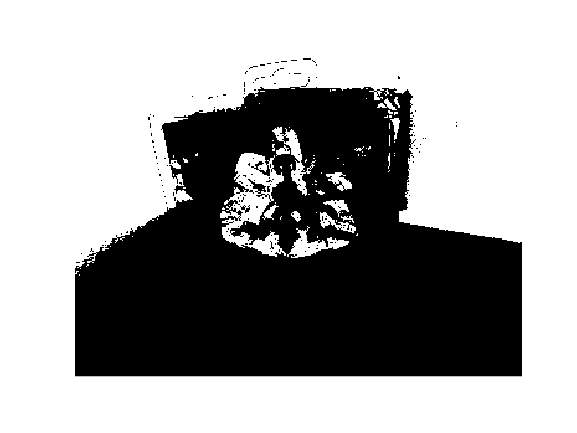

% Shadow Mask
tau = 0.11;
M_shad = (sign(tau + ratio*A_int - F_int) + 1)/2;
M_shad = imerode(M_shad, [1 1; 1 1]);
M_shad = imdilate(M_shad, [1 1; 1 1]);
figure(); imshow(M_shad);

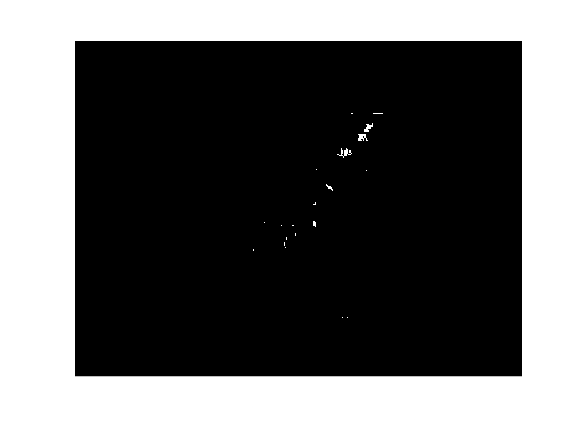

% Specularity Mask
max_val = max(F_int, [], "all");
factor = 0.95;
M_spec = (sign(F_int - factor*max_val) + 1)/2;
M_spec = imerode(M_spec, [1 1 1; 1 1 1; 1 1 1]);
M_spec = imdilate(M_spec, [1 1 1; 1 1 1; 1 1 1]);
figure(); imshow(M_spec);

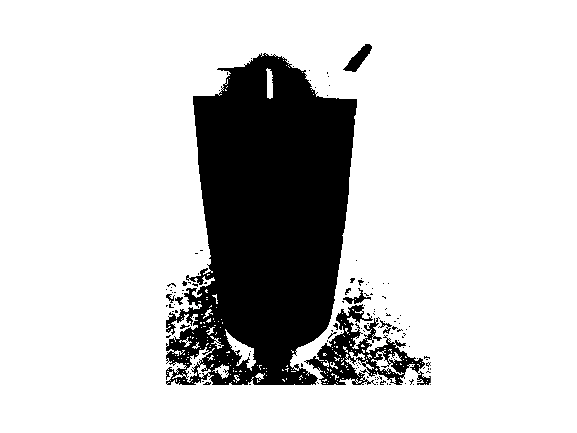

% Union of masks
M = M_shad | M_spec;
figure(); imshow(M);

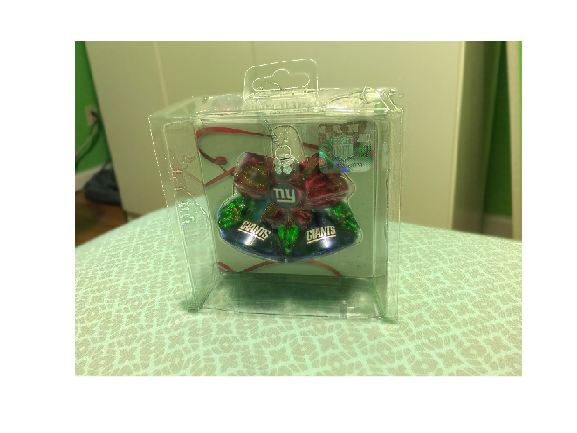

Final = (1-M).*(A_NR.*F_Detail) + M.*A_Base;
figure(); imshow(Final);